#### *Load data*

close all
clear all
clc
path = 'Needs.mat';
load(path)

## Quick data exploration

We start looking at univariate distributions. For example, we check for imbalanced classes

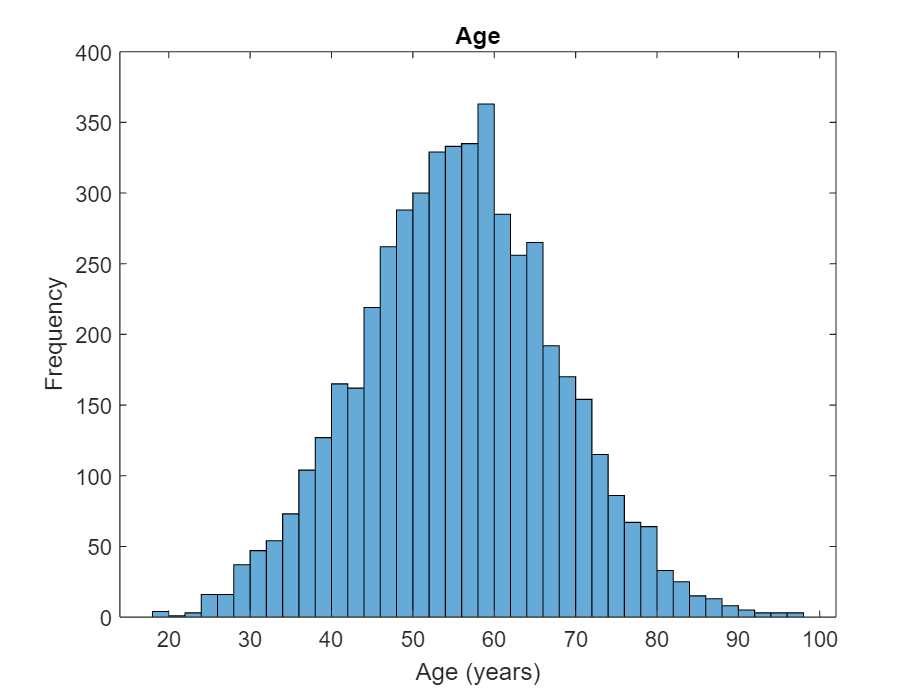

Data = Needs; % renaming

%age
figure
histogram(Data.Age)
title('Age')
xlabel('Age (years)')
ylabel('Frequency')

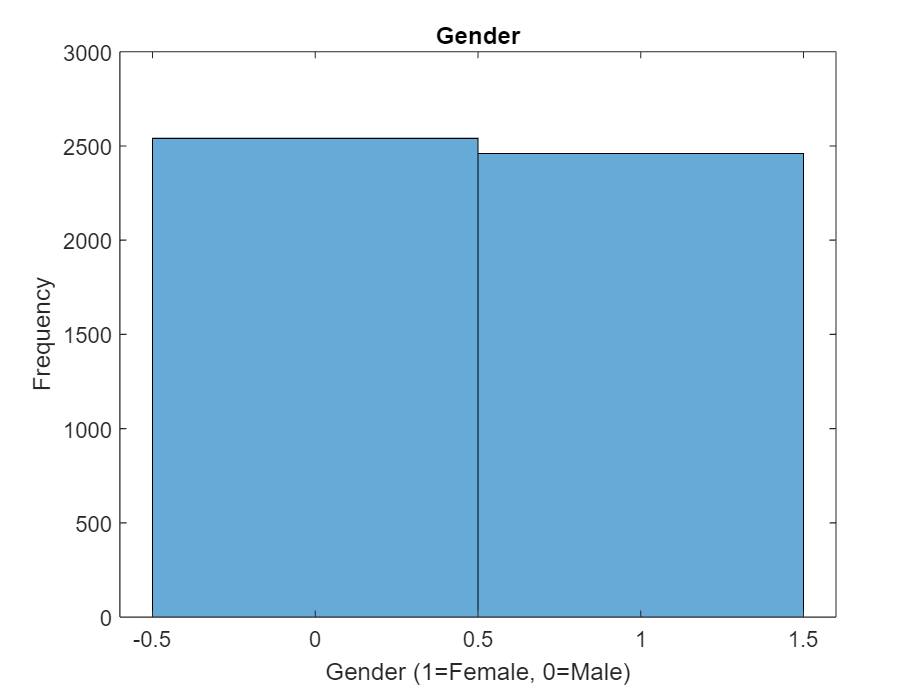

%Gender
figure
histogram(Data.Gender)
title('Gender')
xlabel('Gender (1=Female, 0=Male)')
ylabel('Frequency')

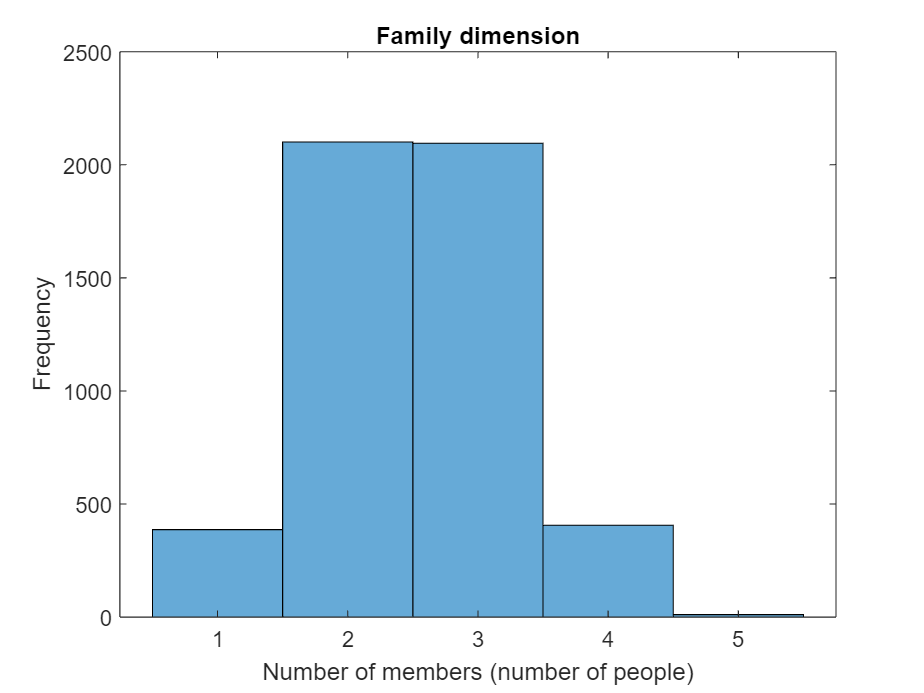

%Family dimension
figure
histogram(Data.FamilyMembers)
title('Family dimension')
xlabel('Number of members (number of people)')
ylabel('Frequency')

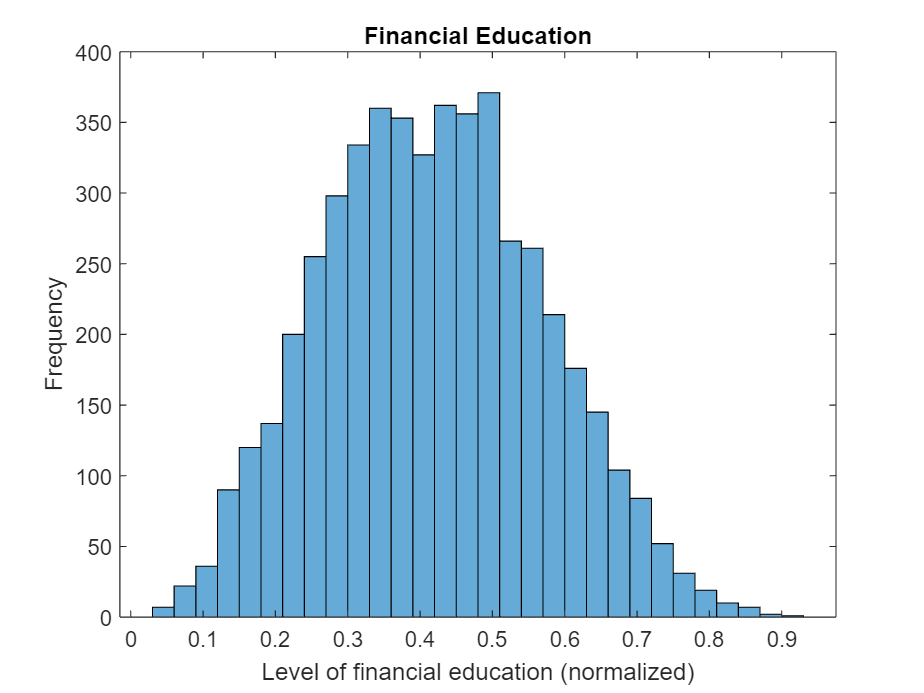

%Financial education
figure
histogram(Data.FinancialEducation)
title('Financial Education')
xlabel('Level of financial education (normalized)')
ylabel('Frequency')

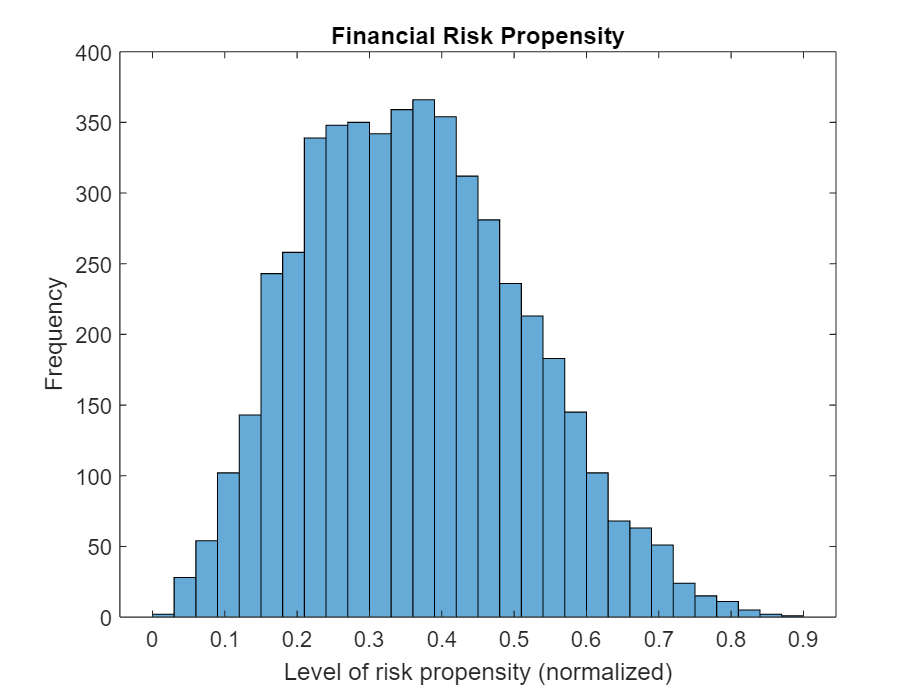

%Financial risk propensity
figure
histogram(Data.RiskPropensity)
title('Financial Risk Propensity')
xlabel('Level of risk propensity (normalized)')
ylabel('Frequency')

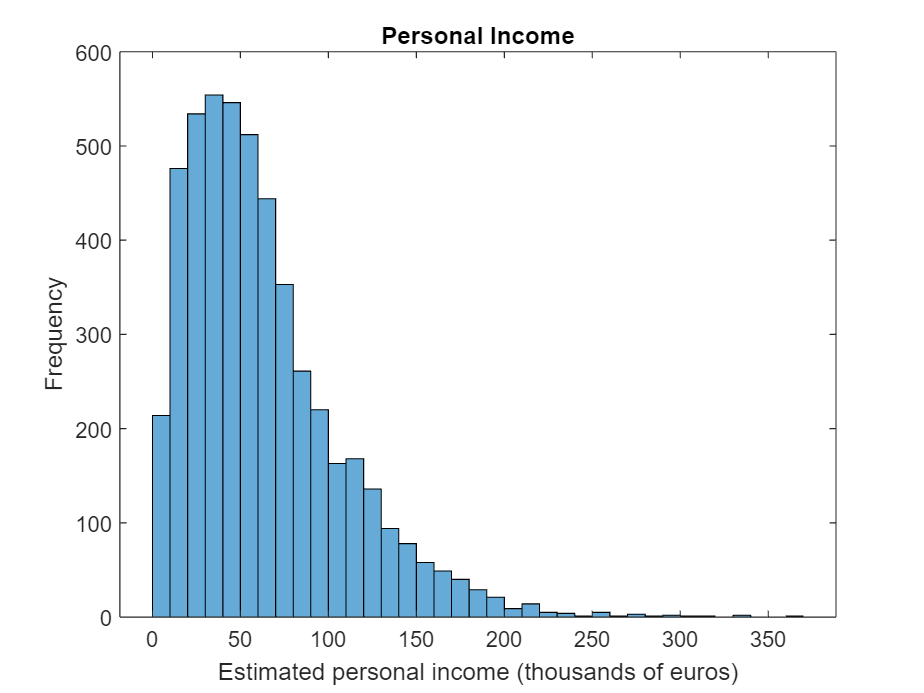

%income
figure
histogram(Data.Income)
title('Personal Income')
xlabel('Estimated personal income (thousands of euros)')
ylabel('Frequency')

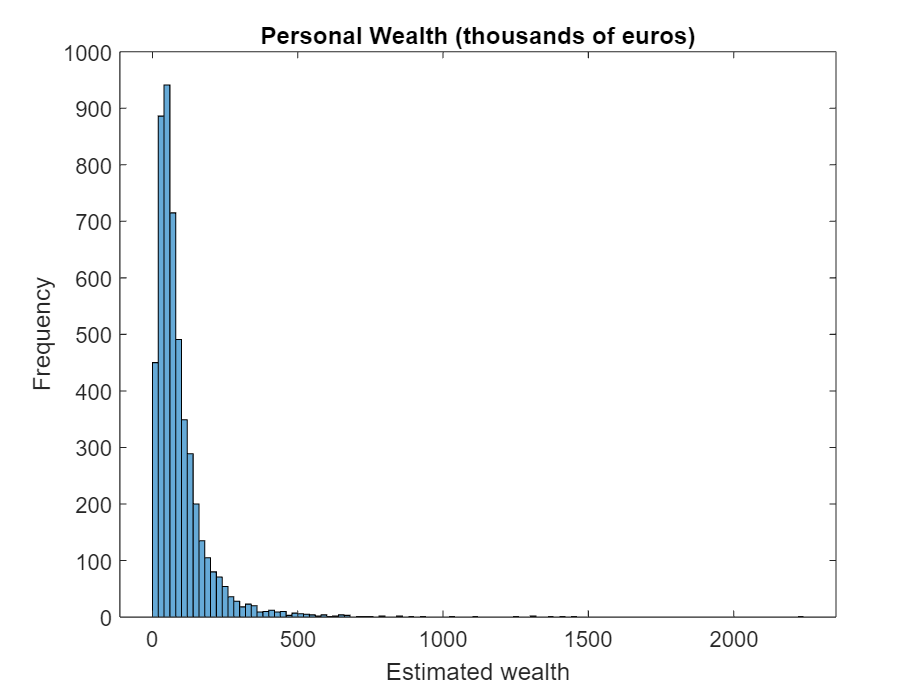

%wealth
figure
histogram(Data.Wealth)
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

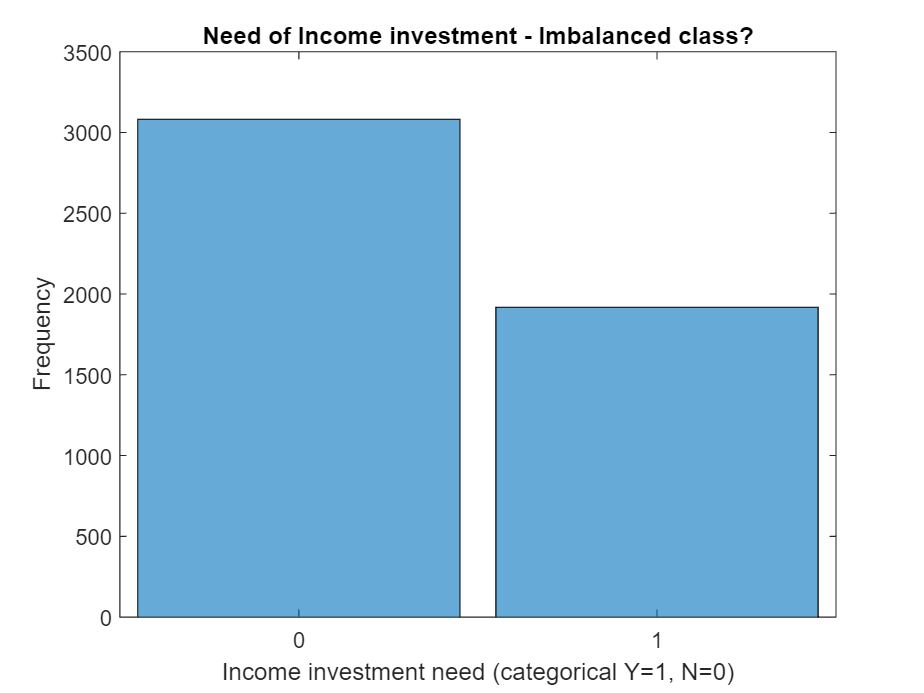

%Income investment
figure
histogram(Data.IncomeInvestment)
title('Need of Income investment - Imbalanced class?')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

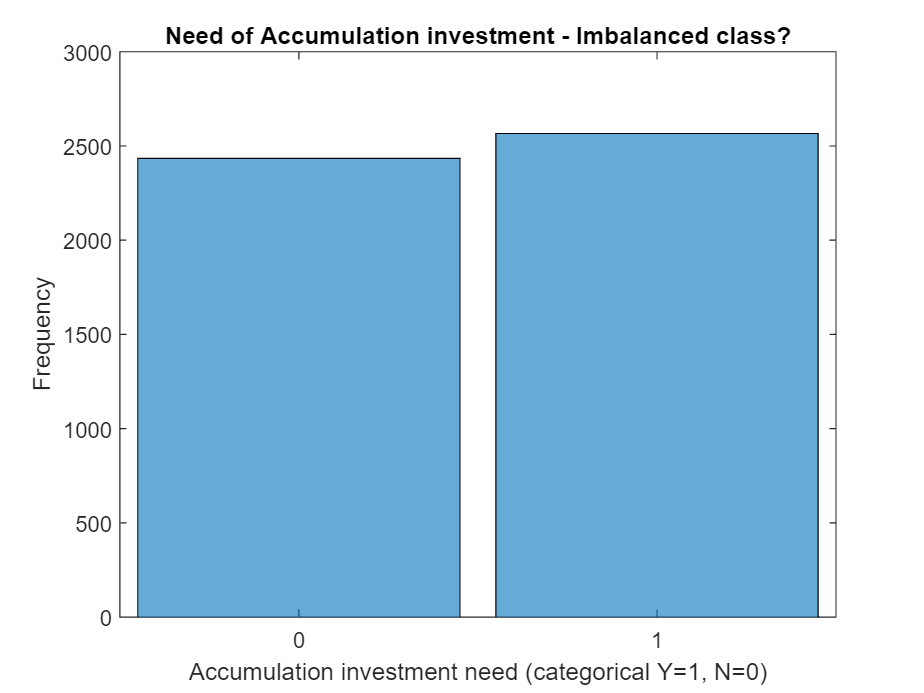

%Accumulation investment
figure
histogram(Data.AccumulationInvestment)
title('Need of Accumulation investment - Imbalanced class?')
xlabel('Accumulation investment need (categorical Y=1, N=0)')
ylabel('Frequency')

### Data transformation

Wealth and Income follow a power law, so we thought it better to use a log transformation and a boxcox transformation to make just a little bit extra nice.

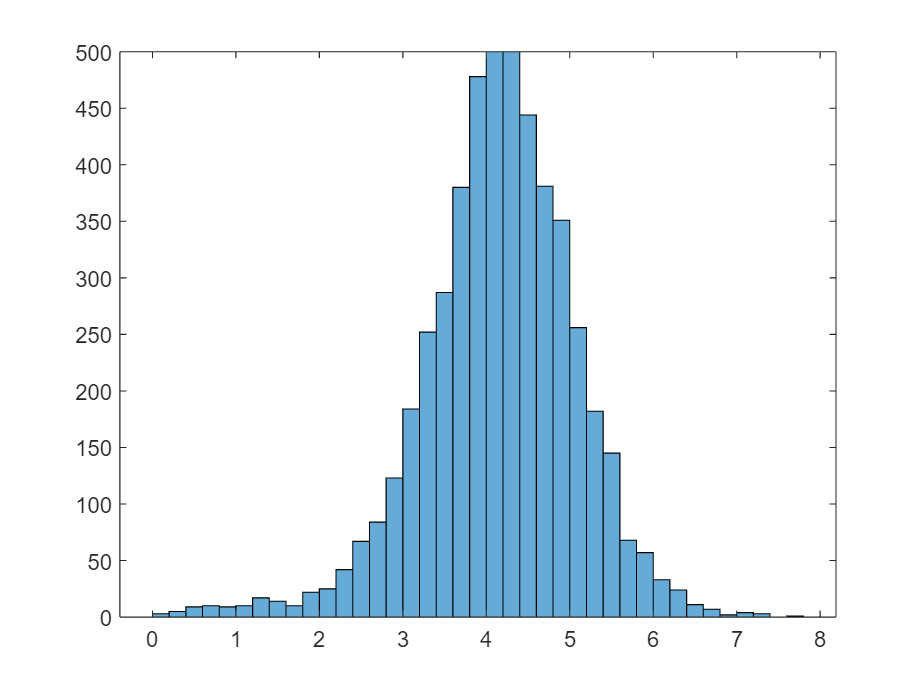

%wealth analysis
histogram(log(Data.Wealth)) % log transformation

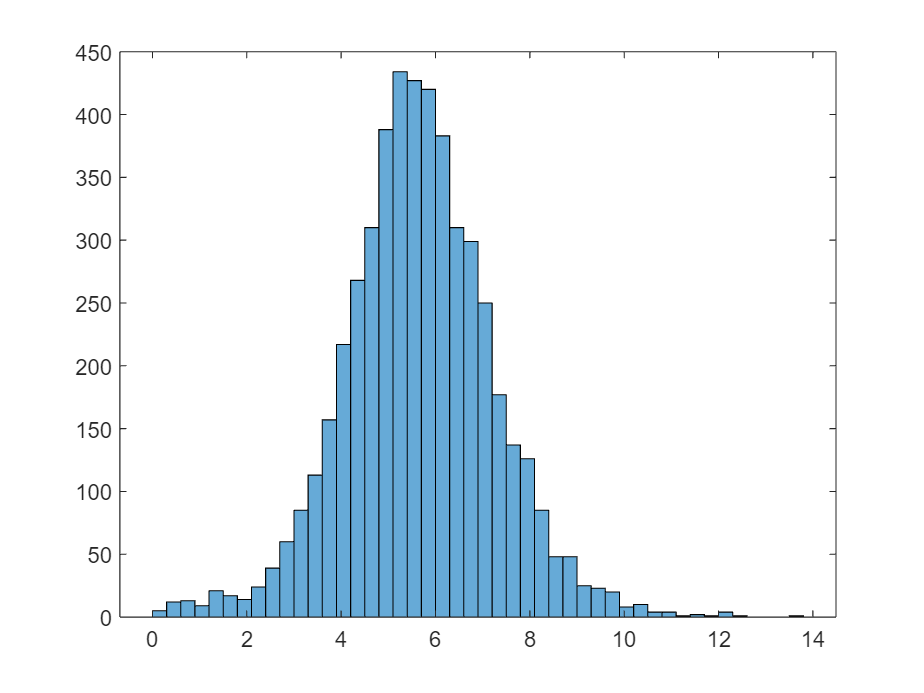

logWealth = log(Data.Wealth); % we'll go for the log-transformation
BoxWealth = boxcox(Data.Wealth);
histogram(BoxWealth); % Boxcox transformation

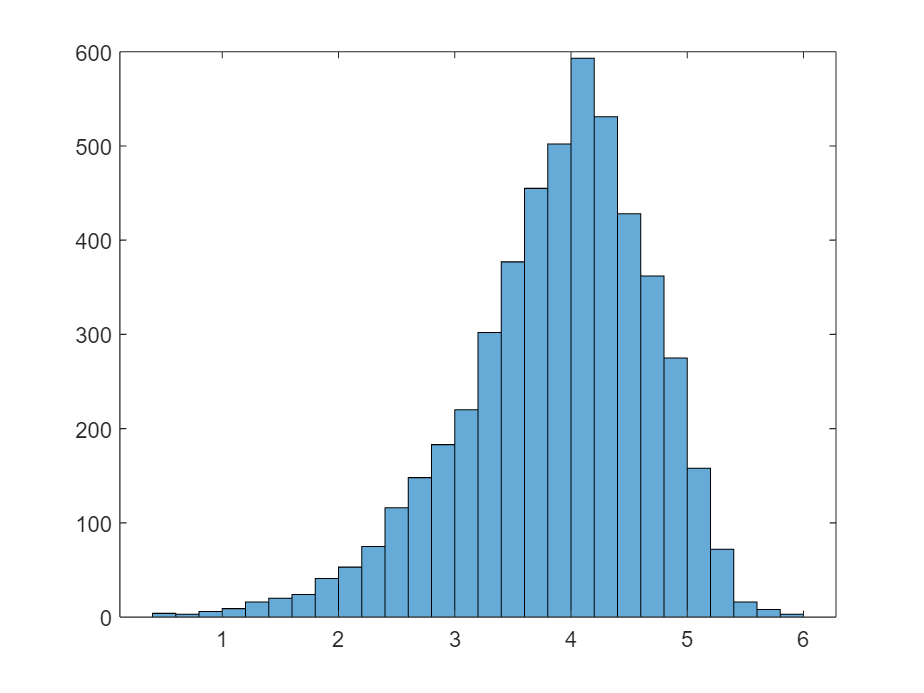

%income analysis
histogram(log(Data.Income)) % log transformation

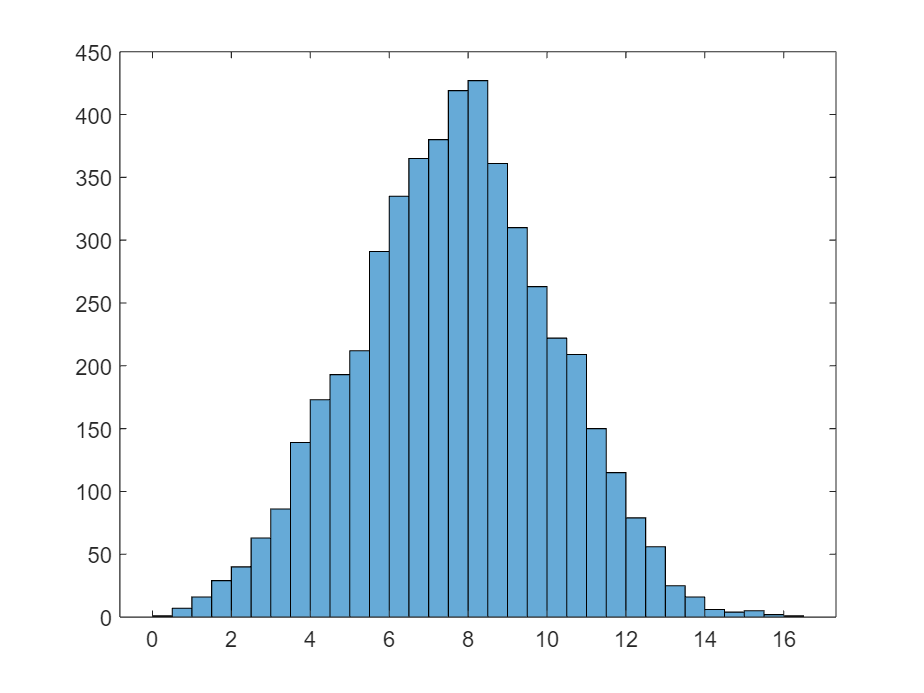

logIncome = log(Data.Income); % we'll go for the log transformation
BoxIncome = boxcox(Data.Income);
histogram(BoxIncome); % boxcox transformation

Now, let's  keep pre-processing our data, checking how scaling and normalization (min/max normalization) affect our data. When you have to measure the distances between pairs of samples, those distances will be influenced by the measurement units used - for example if you use k-NN (key nearest neightborhoods) - normalizing is key. Otherwise it can be less important, as long as the orders of magnitude are the same; so in practice if one variable is in [-1, 2], the other in [0, 4], or [-2, 2], etc, typically is OK.

Consider also that both normalization and scaling are affine transformations (i.e. a+b*x), so they change just the location parameter (i.e. the mean) and the scale parameter (i.e. the standard deviation), NOT the shape of the probability distribution.

*HINT*: in practice, when using a model, try various different pre-processings of the data, without scaling, min/max scaling, z-score, scaling dividing by the sum of absolute values of your data (which would make it to lie on a simplex), etc. This thing is often opaque, as you are (likely) not so sure about the next move, so this video from Andrew NG can be of help: [https://www.youtube.com/watch?v=FDCfw-YqWTE](https://www.youtube.com/watch?v=FDCfw-YqWTE)

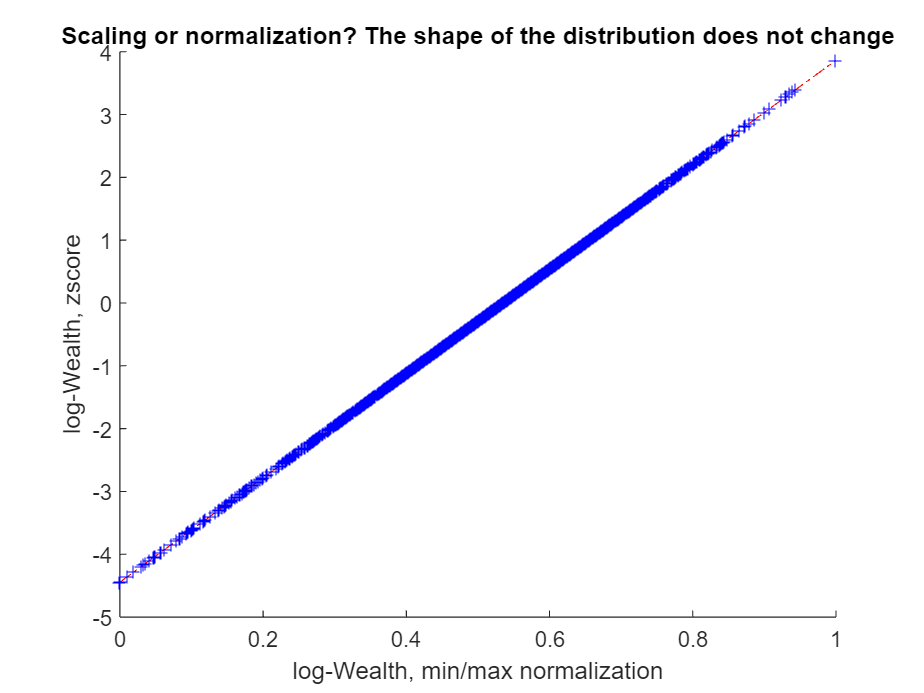

qqplot(rescale(logWealth), zscore(logWealth))
title('Scaling or normalization? The shape of the distribution does not change')
xlabel('log-Wealth, min/max normalization')
ylabel('log-Wealth, zscore')

% X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
    % rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth)];
X =[zscore(Data.Age) Data.Gender zscore(Data.FamilyMembers) zscore(Data.FinancialEducation)...
    zscore(Data.RiskPropensity) zscore(BoxIncome) zscore(BoxWealth)];
Inc = [Data.IncomeInvestment];
Accum = [Data.AccumulationInvestment];

### **Multivariate perspective**

Matrix of scatter plots comparing our Xs by using the our Ys (i.e. investment propensities) as grouping variable (ie we are working on the conditional distribution Prob(X | Y): it is relatively easy to visualize whether each group forms clusters/structures in the scatterplot.

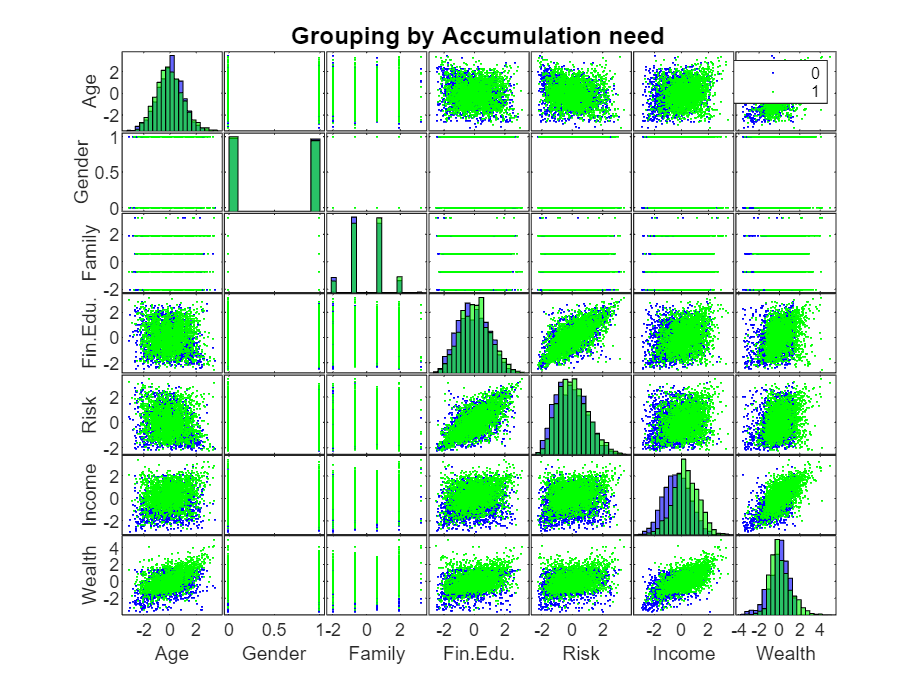

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X,[],Data.AccumulationInvestment, [],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

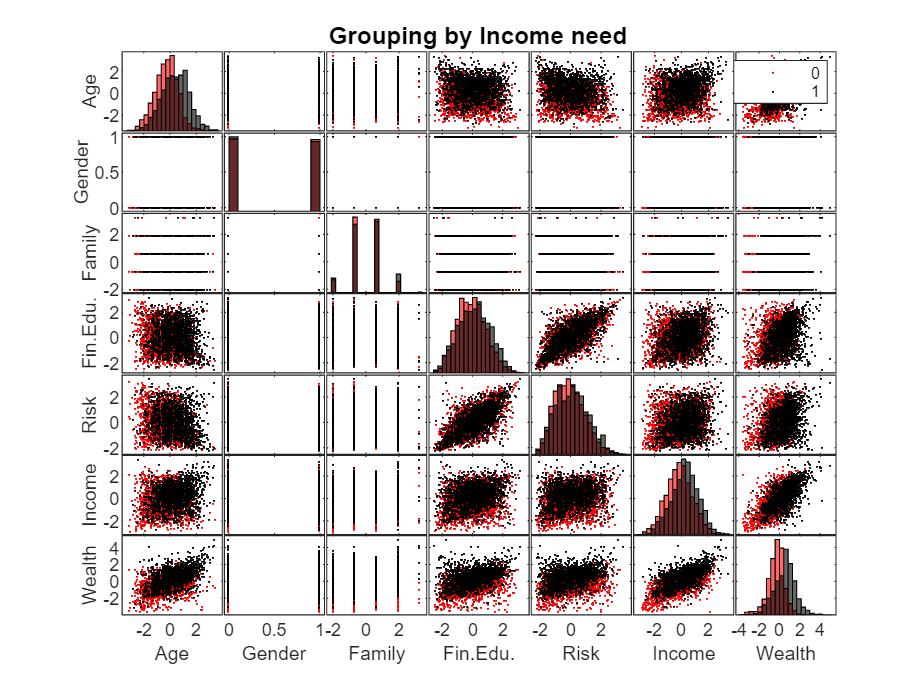

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X,[],Data.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

### Using the classification learner

We use the classification learner, speeding up the modeling process, as it allows for rapid model training/validation, then it generates the code.

### Income Investments model

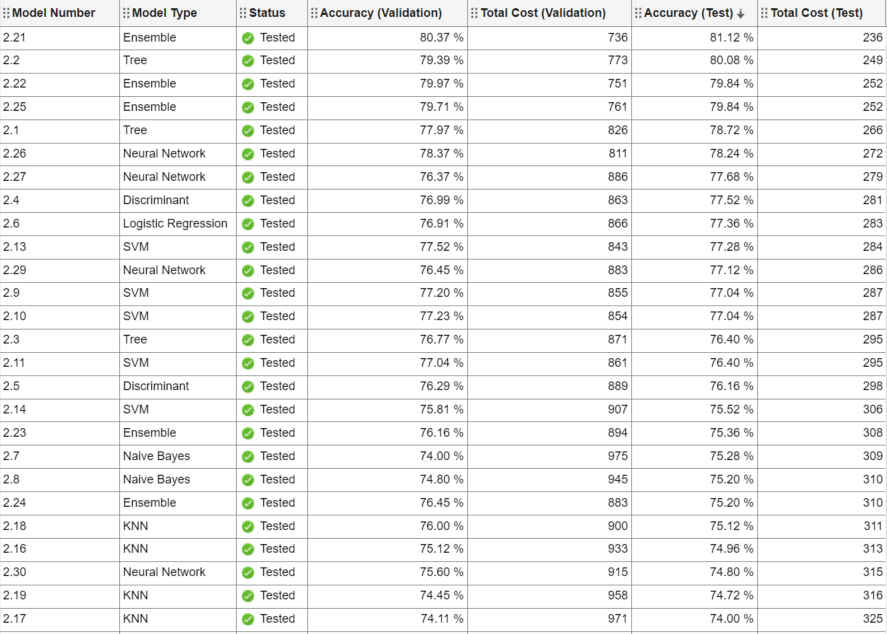We choose accordingly the Ensemble model number 2.21 and we load the model from the file where we saved it:

load('Models/IncomeModel.mat')

### Accumulation investment model

Just as before we do the same but this time we try to predict the need for Accumulation investments: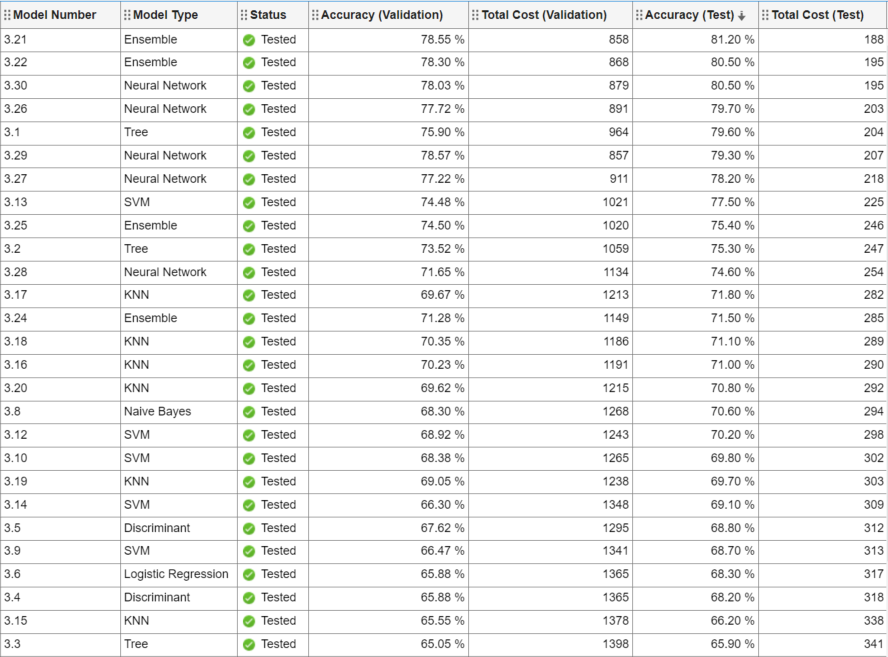

We thus load the corresponding model:

load('Models/AccumulationModel.mat')